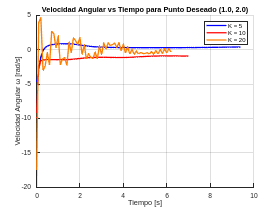

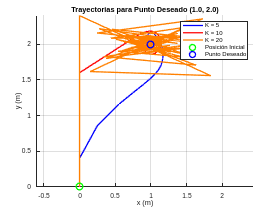

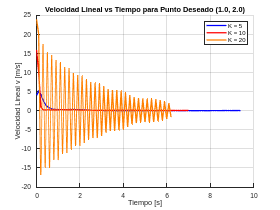

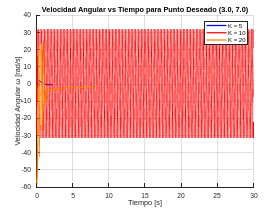

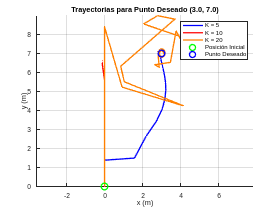

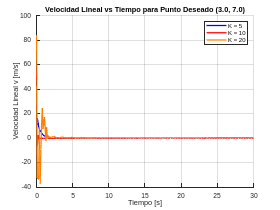

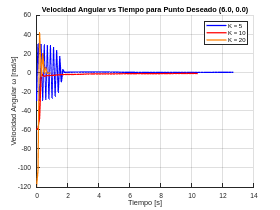

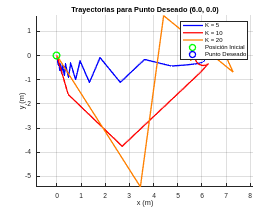

clear all

close all
clc

% 1. TIEMPO
tf = 15;             
ts = 0.1;            
t = 0:ts:tf;         
N = length(t);      
umbral_error = 0.1;

% 2. LISTA DE PUNTOS DESEADOS
puntos =     [  1,    2;
                3,    7;
                6,    0;
               -4,    5;
               -6,    0;
               -1,    0;
               -7,   -7;
               -2,   -4;
               -0.5, -0.5;
                1,   -3;
                3,   -5;
                8,    0;
                0,   -3;
                0,    9;
                0,   -1;
               -5,  -10;
                7,   -7;
                3,   -1;
              -10,  -10;
               10,    9];

% 3. LISTA DE GANANCIAS
ganancias = cat(3, ...
    [2 0; 0 2], ...
    [8 0; 0 8], ...
    [12 0; 0 12]);

colores = {'b', 'r', 'c'};


% 4. Simulación para cada punto
for idx = 1:size(puntos, 1)
    hxd = puntos(idx,1);
    hyd = puntos(idx,2);

    % Inicializar figuras para graficar todo junto
    figure_tray = figure('Name', 'Trayectoria comparativa');
    hold on; grid on; axis equal;
    xlabel('x (m)'); ylabel('y (m)');
    title(sprintf('Trayectorias para Punto Deseado (%.1f, %.1f)', hxd, hyd));

    figure_v = figure('Name', 'Velocidad lineal comparativa');
    hold on; grid on;
    xlabel('Tiempo [s]'); ylabel('Velocidad Lineal v [m/s]');
    title(sprintf('Velocidad Lineal vs Tiempo para Punto Deseado (%.1f, %.1f)', hxd, hyd));

    figure_w = figure('Name', 'Velocidad angular comparativa');
    hold on; grid on;
    xlabel('Tiempo [s]'); ylabel('Velocidad Angular ω [rad/s]');
    title(sprintf('Velocidad Angular vs Tiempo para Punto Deseado (%.1f, %.1f)', hxd, hyd));

    for g = 1:size(ganancias, 3)
        K = ganancias(:, :, g);

        % Reiniciar condiciones iniciales
        x1 = zeros(1, N);  
        y1 = zeros(1, N);  
        phi = zeros(1, N);
        phi(1) = pi/2;
        hx = zeros(1, N);       
        hy = zeros(1, N);       
        hx(1) = x1(1);
        hy(1) = y1(1);
        v = zeros(1, N);
        w = zeros(1, N);
        Error = zeros(1, N);

        % Simulación
        for k = 1:N
            hxe = hxd - hx(k);
            hye = hyd - hy(k);
            he = [hxe; hye];
            Error(k) = norm(he);

            % Jacobiana y ley de control
            J = [cos(phi(k)) -sin(phi(k));
                 sin(phi(k))  cos(phi(k))];
            qpRef = pinv(J) * K * he;
            v(k) = qpRef(1);   
            w(k) = qpRef(2);   

            % Modelo cinemático
            phi(k+1) = phi(k) + w(k) * ts;
            xp1 = v(k) * cos(phi(k)); 
            yp1 = v(k) * sin(phi(k));
            x1(k+1) = x1(k) + xp1 * ts;
            y1(k+1) = y1(k) + yp1 * ts;
            hx(k+1) = x1(k+1); 
            hy(k+1) = y1(k+1);

            if Error(k) < umbral_error
                break
            end
        end

        k_end = find(Error < umbral_error, 1);
        if isempty(k_end)
            k_end = N;
        end

        % Graficar trayectorias
        figure(figure_tray);
        plot(hx(1:k_end), hy(1:k_end), 'Color', colores{g}, 'LineWidth', 2, 'DisplayName', sprintf('K = %d', K(1,1)));

        % Graficar velocidades
        figure(figure_v);
        plot(t(1:k_end), v(1:k_end), 'Color', colores{g}, 'LineWidth', 2, 'DisplayName', sprintf('K = %d', K(1,1)));

        figure(figure_w);
        plot(t(1:k_end), w(1:k_end), 'Color', colores{g}, 'LineWidth', 2, 'DisplayName', sprintf('K = %d', K(1,1)));
    end

    % Agregar leyenda y marcas de posición
    figure(figure_tray);
    plot(0, 0, 'go', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Posición Inicial');
    plot(hxd, hyd, 'bo', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Punto Deseado');
    legend show;

    figure(figure_v); legend show;
    figure(figure_w); legend show;
end